Definicja transmitancji:


$$G(s) = \frac{0.3s^2 + 2.5s + 65}{0.0024s^4 + 0.05s^3 + 8.03s^2 + 94s + 223}$$


G = tf([0.3, 2.5, 65], [0.0024, 0.05, 8.03, 94, 223]);

Wyrysowanie plotu Michajłowa:

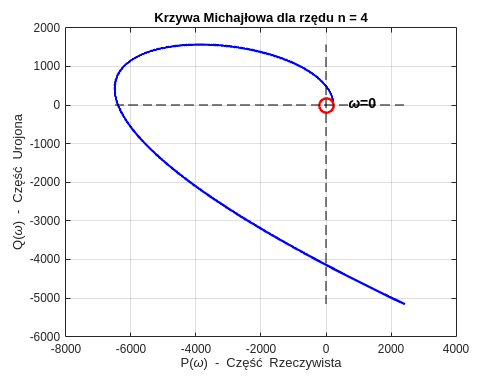

den = G.Denominator{1};

% Rząd układu (potrzebny do weryfikacji kryterium)
n = length(den) - 1;

% Wektor częstości omega
% Uwaga: Zakres trzeba dobrać eksperymentalnie, żeby zobaczyć wszystkie ćwiartki
w = 0:0.05:60;

% Obliczenie wartości wielomianu M(jw)
M_jw = polyval(den, 1i*w);

% Wyodrębnienie części rzeczywistej P(w) i urojonej Q(w)
P = real(M_jw);
Q = imag(M_jw);

% Wizualizacja
f = figure;
plot(P, Q, 'b-', 'LineWidth', 2); hold on;
plot(0, 0, 'ro', 'MarkerSize', 12, 'LineWidth', 2); % Zaznaczenie (0,0)

% Oznaczenie początku wykresu (omega = 0)
text(P(1), Q(1), '  \omega=0', 'FontSize', 12, 'FontWeight', 'bold');

% Kosmetyka wykresu
grid on;
xlabel('P(\omega) - Część Rzeczywista');
ylabel('Q(\omega) - Część Urojona');
title(['Krzywa Michajłowa dla rzędu n = ', num2str(n)]);

% Rysowanie osi układu współrzędnych
line([min(P) max(P)], [0 0], 'Color', 'k', 'LineStyle', '--'); % Oś X
line([0 0], [min(Q) max(Q)], 'Color', 'k', 'LineStyle', '--'); % Oś Y

Krzywa Michajłowa przechodzi przez 4 ćwiartki układu współrzędnych. Symbolicznie sprawdzamy do jakiego kąta dąży w nieskończoności.

syms s w real positive % Definiujemy omegę jako zmienną symboliczną rzeczywistą dodatnią
% Konwersja współczynników wielomianu na postać symboliczną M(jw)
% Tworzymy wielomian zmiennej zespolonej s = j*w
M_s = poly2sym(den, s);
M_sym = subs(M_s, s, 1i*w);

% Obliczenie kąta (fazy) wielomianu
% angle(z) w MATLAB symbolicanym zwraca atan2(Im, Re)
faza_sym = angle(M_sym);

% Obliczenie granicy przy omega dążącym do nieskończoności
granica_fazy = limit(faza_sym, w, Inf);

fprintf('Symbolicznie obliczona granica fazy przy w -> Inf: %s rad\n', char(granica_fazy));

Symbolicznie obliczona granica fazy przy w -> Inf: 0 rad


% Weryfikacja teoretyczna
teoretyczna_faza = n * pi / 2;
fprintf('Teoretycznie wymagana całkowita zmiana fazy (n * pi/2): %.2f rad\n', teoretyczna_faza);

Teoretycznie wymagana całkowita zmiana fazy (n * pi/2): 6.28 rad


if abs(double(granica_fazy)) < teoretyczna_faza
    disp('UWAGA: Obliczona granica różni się od teoretycznej całkowitej zmiany fazy.');
    disp('Wynika to z faktu, że funkcja "angle" zwraca wynik w zakresie (-pi, pi].');
    disp('Dla n >= 3 następuje "zawijanie fazy" (phase wrapping).');
    disp(['Dla n=', num2str(n), ' właściwa interpretacja to: ', num2str(n), ' * pi/2']);
else
    disp('Obliczona granica zgadza się z teorią.');
end

UWAGA: Obliczona granica różni się od teoretycznej całkowitej zmiany fazy.


Wynika to z faktu, że funkcja "angle" zwraca wynik w zakresie (-pi, pi].


Dla n >= 3 następuje "zawijanie fazy" (phase wrapping).


Dla n=4 właściwa interpretacja to: 4 * pi/2
